clear all; close all; clc;

sample_count = 400

sample_count = 400

width = 424;
height = 240;

wo_path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/wo_glare/beforeCSV_file_for_cloud_";
wo_path_postfix = ".csv";

wo_glare_tensor = zeros(height,width,sample_count);

sample_count = 400

sample_count = 400

width = 424;
height = 240;

path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

glare_tensor = zeros(height,width,sample_count);

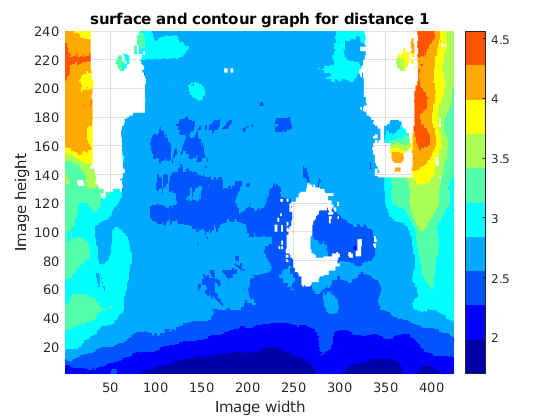

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
        plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end

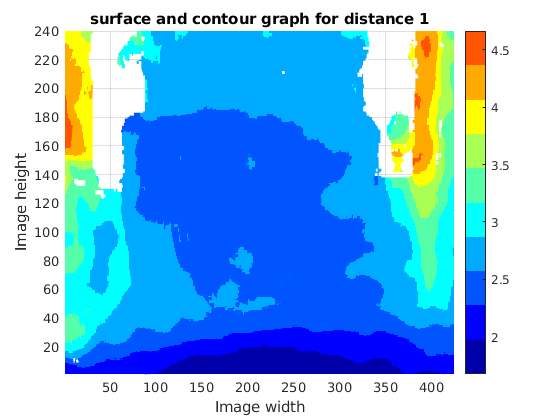

for callback_count = 1:sample_count
    
    h = string(callback_count);
    wo_path = wo_path_pefix+h+wo_path_postfix;
    data = csvread(wo_path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    wo_glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
        plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end

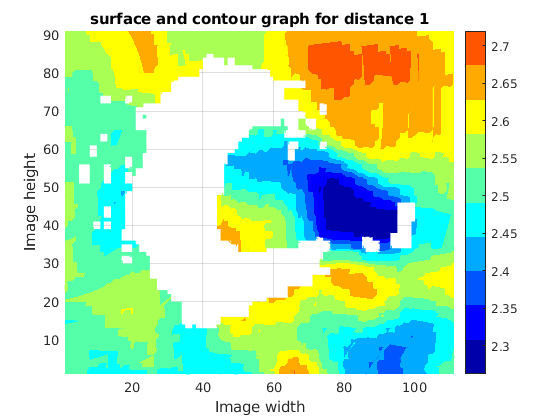

% filtering
wo_glare_tensor_f = wo_glare_tensor(50:140,225:335,:);
glare_tensor_f = glare_tensor(50:140,225:335,:);

mat2g = wo_glare_tensor_f(:,:,2);
mat2wg = glare_tensor_f(:,:,1);

size(mat2g);
size(mat2wg);

plotter(111,91,mat2wg,title_,z_label,save_,0)

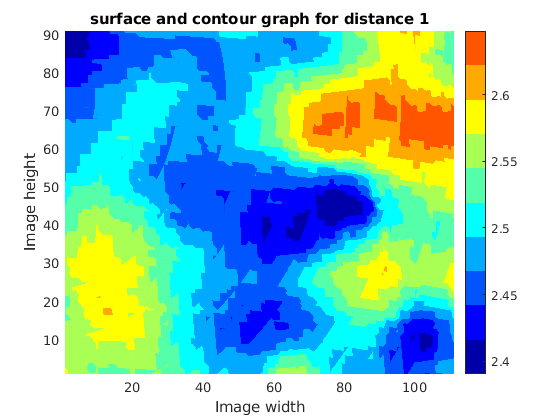

plotter(111,91,mat2g,title_,z_label,save_,0)


width_f = 111

width_f = 111

height_f = 91

height_f = 91

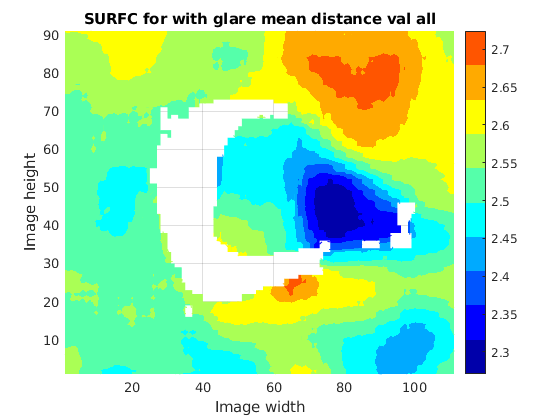

mean_map = nanmean(glare_tensor_f,3);
z_label = "mean distance val";
save_ = "all";
title_ = "SURFC for with glare "+z_label+" "+save_;
plotter(width_f,height_f,mean_map,title_,z_label,save_,0)

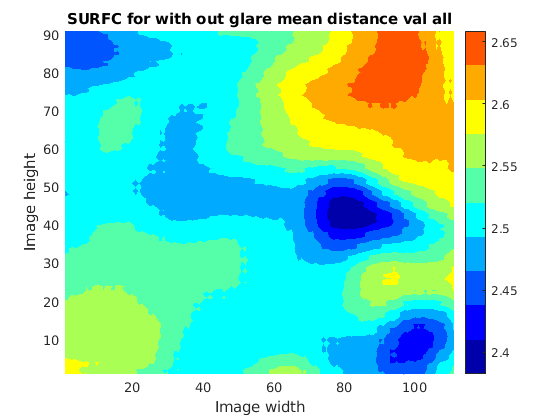


wo_mean_map = nanmean(wo_glare_tensor_f,3);
z_label = "mean distance val";
save_ = "all";
title_ = "SURFC for with out glare "+z_label+" "+save_;
plotter(width_f,height_f,wo_mean_map,title_,z_label,save_,0)

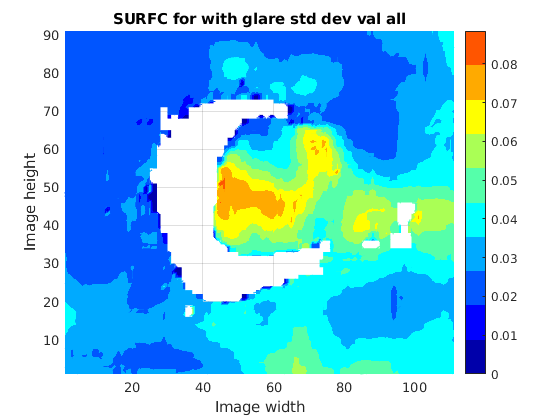

stddev_map = nanstd(glare_tensor_f,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "SURFC for with glare "+z_label+" "+save_;
% z_lim = 0.25;
plotter(width_f,height_f,stddev_map,title_,z_label,save_,0)

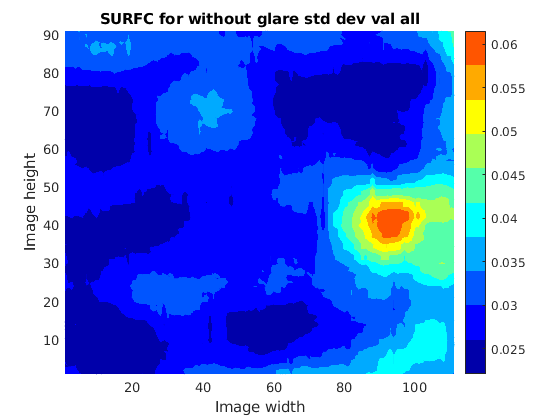


wo_stddev_map = nanstd(wo_glare_tensor_f,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "SURFC for without glare "+z_label+" "+save_;
% z_lim = 0.25;
plotter(width_f,height_f,wo_stddev_map,title_,z_label,save_,0)

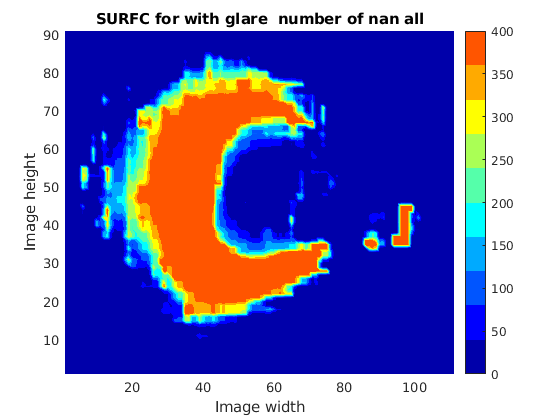

no_of_nan_mat = zeros(size(mean_map));
for h=1:height_f
    for w=1:width_f
        temp_3d = glare_tensor_f(h,w,:);
        temp_1d = reshape(temp_3d, [1,sample_count]);
        no_of_nan_mat(h,w) = sum(isnan(temp_1d));
    end
end
% no_of_nan_mat = sample_count*ones(size(no_of_nan_mat)) - no_of_nan_mat;
z_label = "number of nan";
save_ = "all";
title_ = "SURFC for with glare  "+z_label+" "+save_;
plotter(width_f,height_f,no_of_nan_mat,title_,z_label,save_,0)

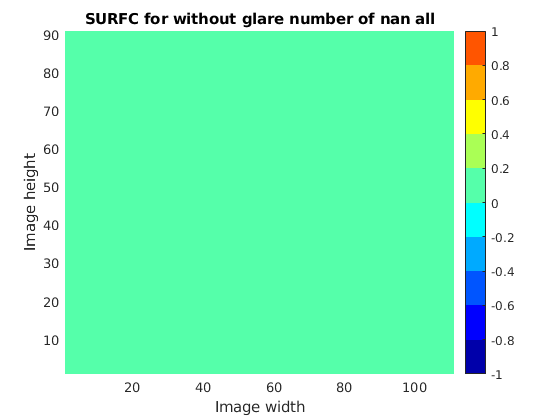


wo_no_of_nan_mat = zeros(size(mean_map));
for h=1:height_f
    for w=1:width_f
        wo_temp_3d = wo_glare_tensor_f(h,w,:);
        wo_temp_1d = reshape(temp_3d, [1,sample_count]);
        wo_no_of_nan_mat(h,w) = sum(isnan(wo_temp_1d));
    end
end
% wo_no_of_nan_mat = sample_count*ones(size(wo_no_of_nan_mat)) - wo_no_of_nan_mat;
z_label = "number of nan";
save_ = "all";
title_ = "SURFC for without glare "+z_label+" "+save_;
plotter(width_f,height_f,wo_no_of_nan_mat,title_,z_label,save_,0)

Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat,wo_mean_map,wo_stddev_map,wo_no_of_nan_mat);

ans =          0         0         0         0         0    0.0996    0.2769    0.4944         0   13.4327    9.9662   15.4208   20.6479   15.6330   12.1506   13.2335   12.9109   16.0075   17.5827   12.9512    8.2966    7.4911    7.7751       Inf    6.2293    5.2160    5.0365    3.5373   11.4550    2.8678    2.3139       Inf       Inf       Inf    3.1746    3.5279    2.7105    1.8212    1.5275    0.4725         0         0         0   75.1085   77.7537   32.3668       Inf       Inf       Inf   22.5724


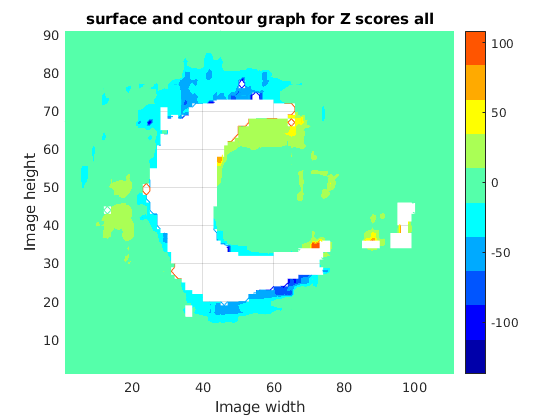

z_label = "Z scores";
save_ = "all";
title_ = "surface and contour graph for "+z_label+" "+save_;
plotter(width_f,height_f,Z_score_matrix,title_,z_label,save_,0)


z_99_conf = 5

z_99_conf = 5

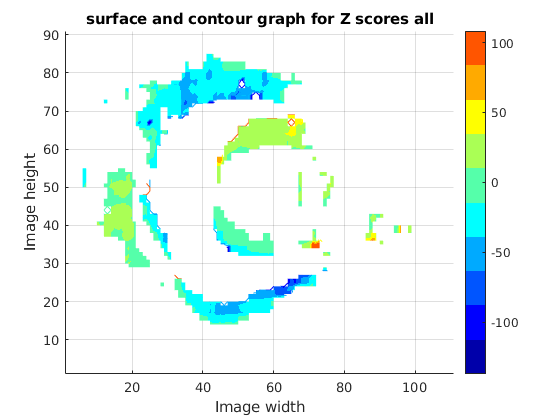

Z_score_matrix(abs(Z_score_matrix(:,:))<z_99_conf) = NaN;

plotter(width_f,height_f,Z_score_matrix,title_,z_label,save_,0)

height = 36

width = 73

no_of_nan = 0

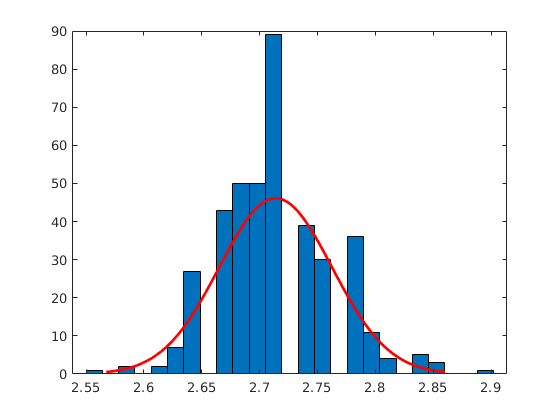

height = 69

width = 31

no_of_nan = 0

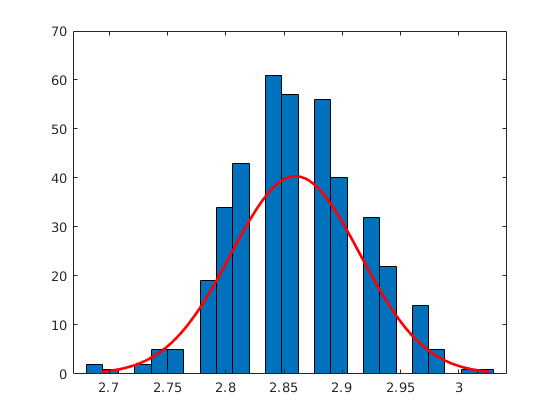

height = 24

width = 57

no_of_nan = 0

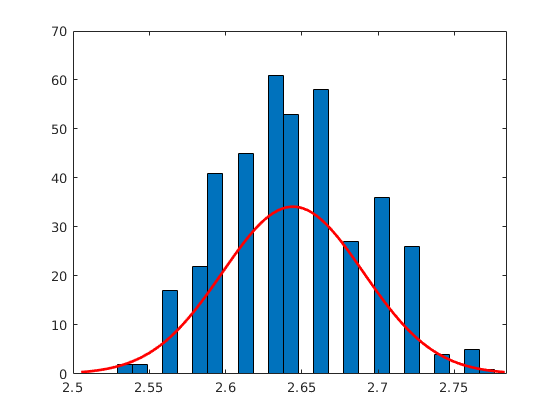

height = 73

width = 35

no_of_nan = 0

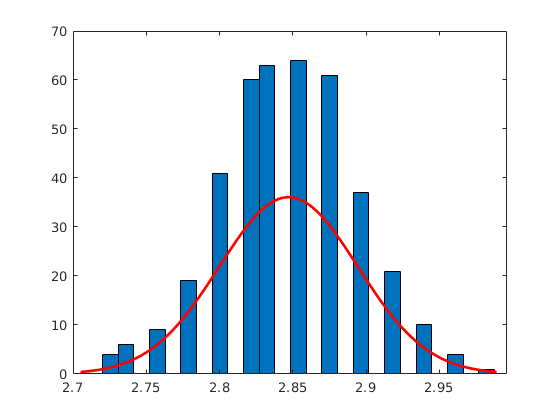

height = 49

width = 19

no_of_nan = 0

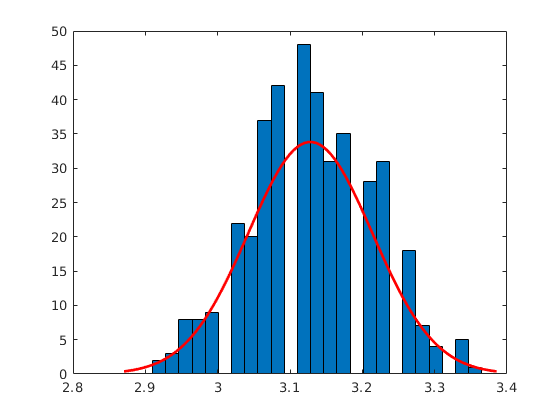

height = 76

width = 60

no_of_nan = 0

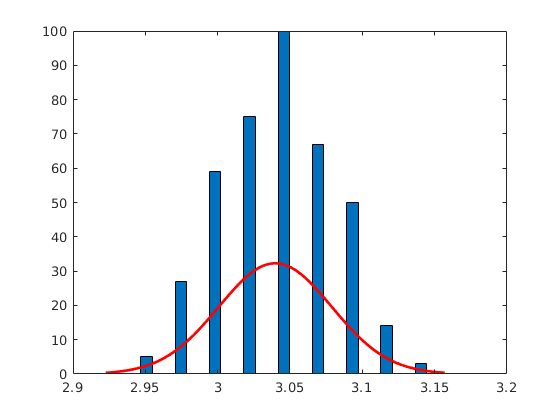

height = 37

width = 29

no_of_nan = 0

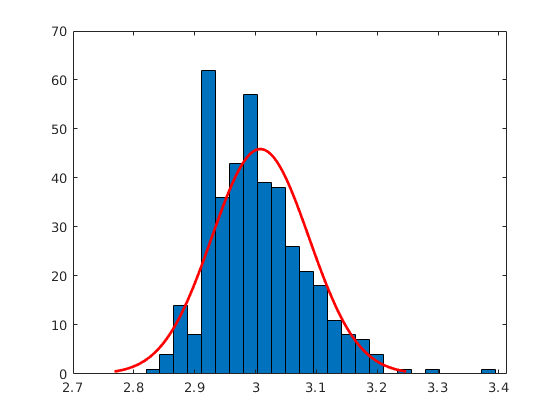

height = 73

width = 48

no_of_nan = 0

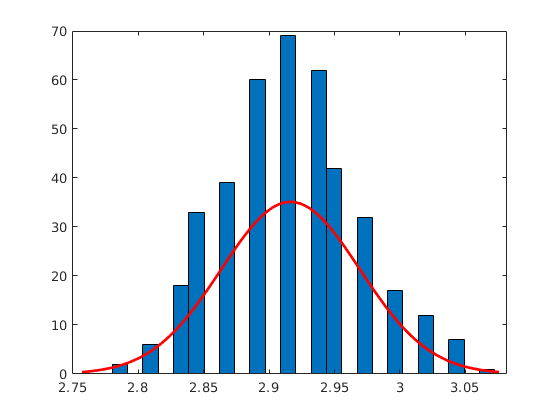

height = 82

width = 41

no_of_nan = 0

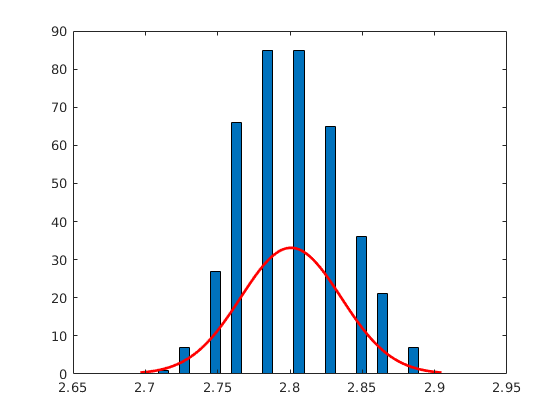

height = 17

width = 41

no_of_nan = 0

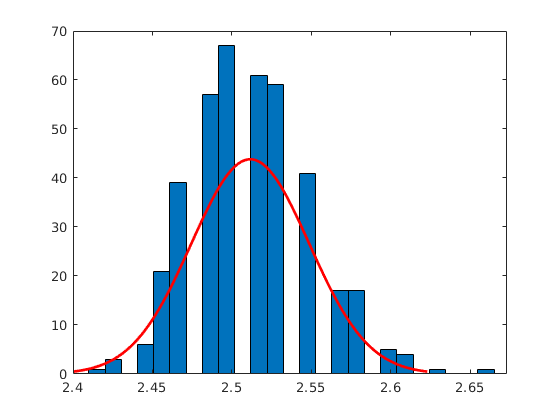

height = 35

width = 91

no_of_nan = 0

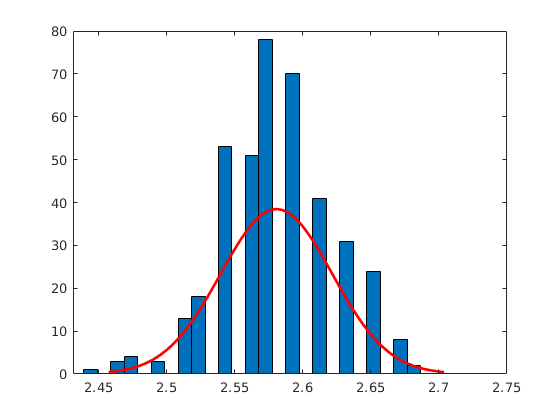

height = 24

width = 67

no_of_nan = 0

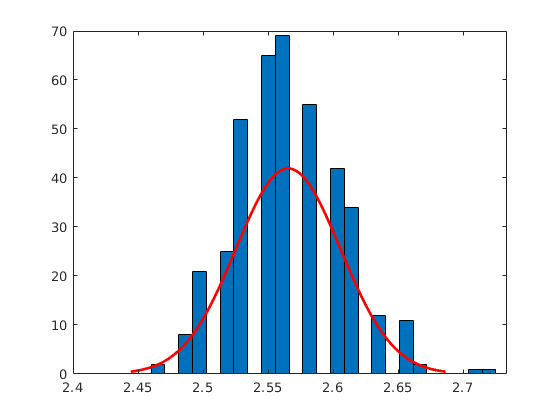

height = 65

width = 25

no_of_nan = 0

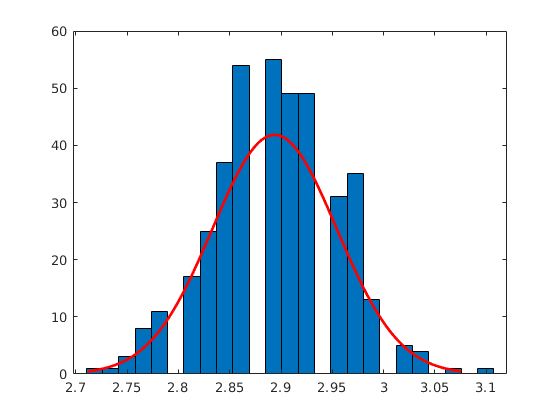

height = 67

width = 55

no_of_nan = 0

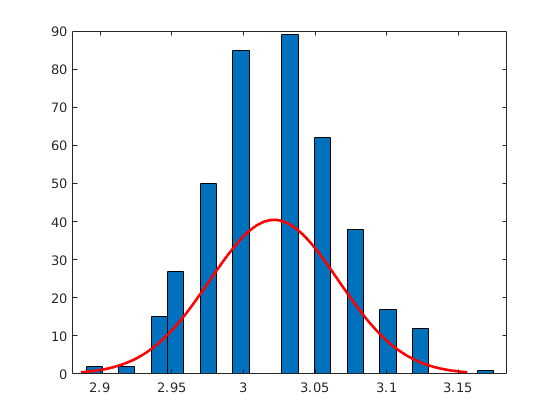

height = 22

width = 55

no_of_nan = 0

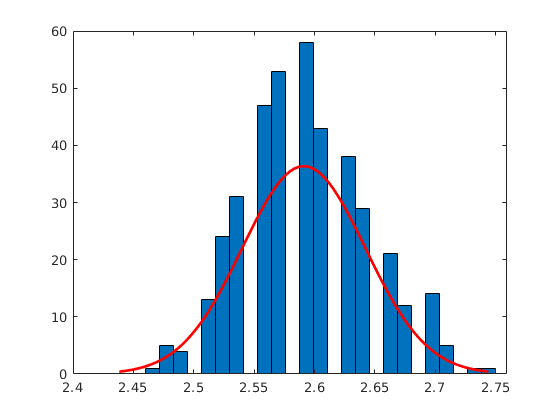

height = 60

width = 55

no_of_nan = 0

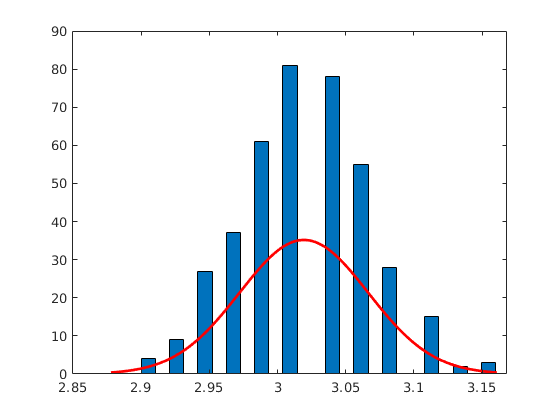

height = 68

width = 56

no_of_nan = 0

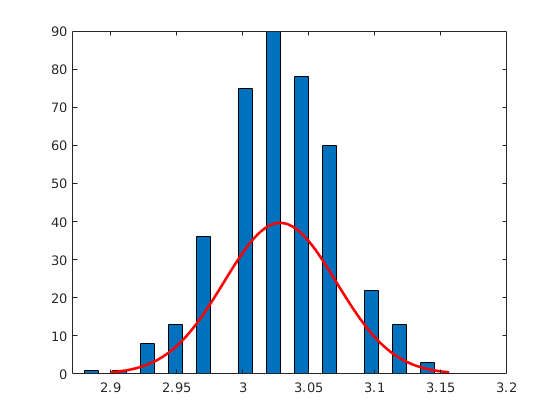

height = 65

width = 56

no_of_nan = 0

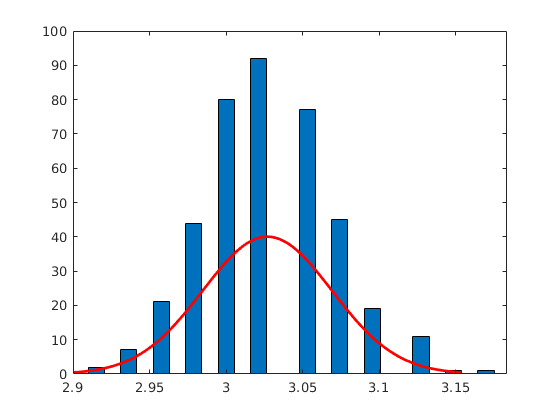

height = 19

width = 55

no_of_nan = 0

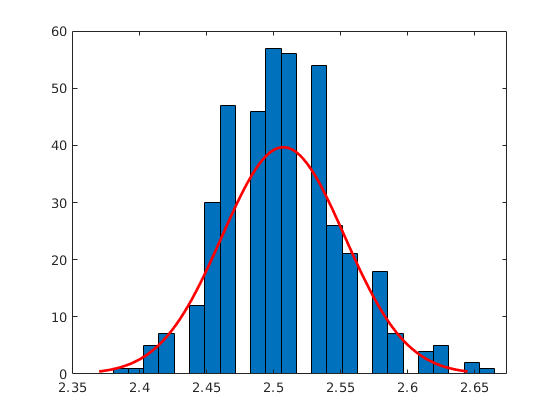

height = 68

width = 30

no_of_nan = 0

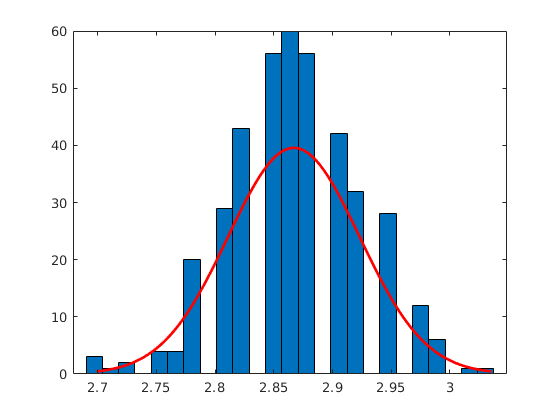

height = 34

width = 52

no_of_nan = 0

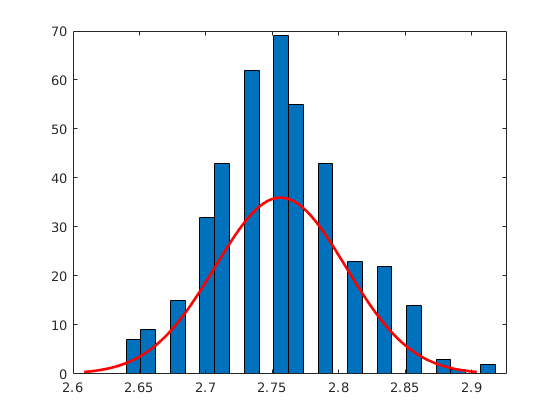

height = 27

width = 69

no_of_nan = 0

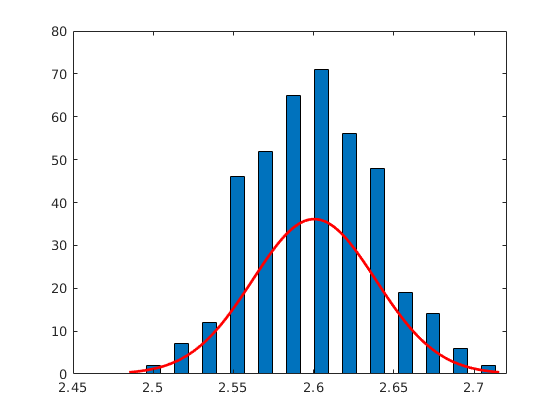

height = 24

width = 66

no_of_nan = 0

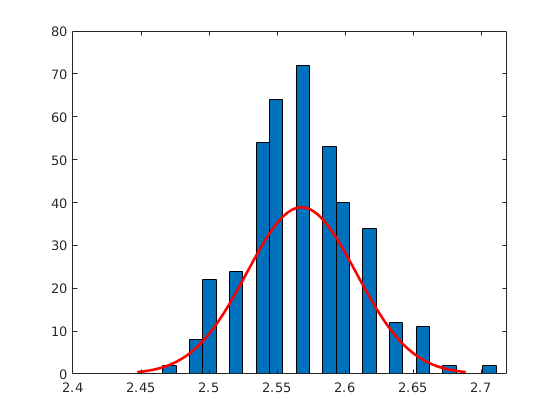

height = 17

width = 47

no_of_nan = 0

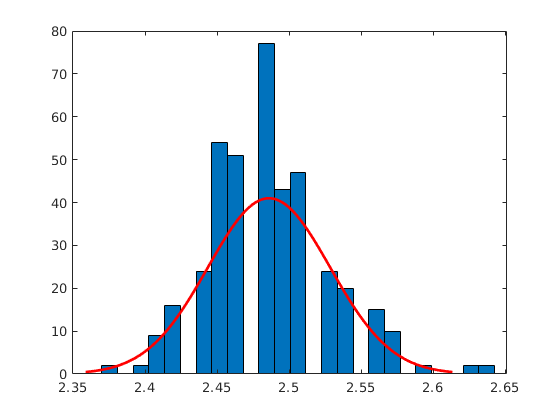

height = 60

width = 46

no_of_nan = 0

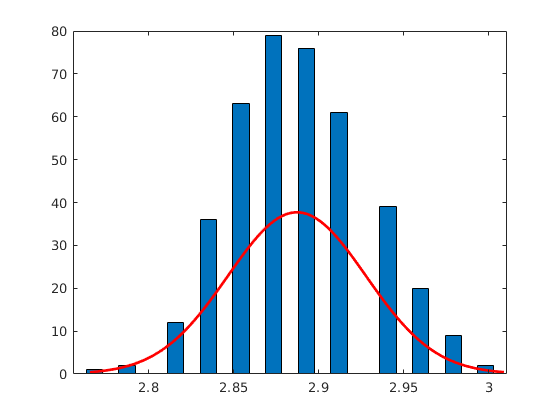

height = 80

width = 58

no_of_nan = 0

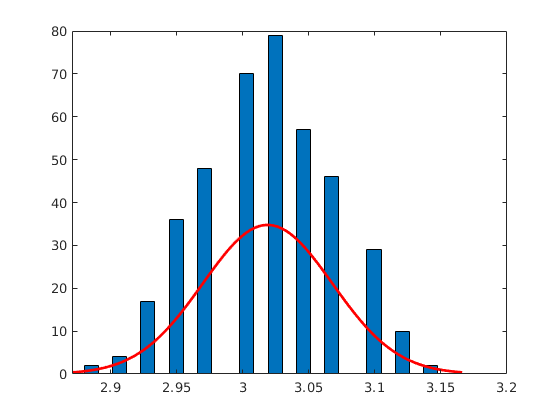

height = 77

width = 39

no_of_nan = 0

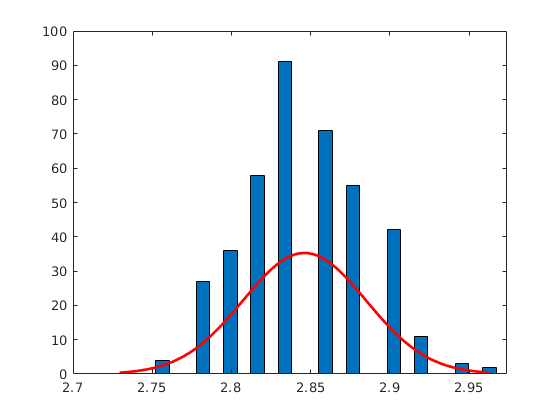

height = 71

width = 36

no_of_nan = 0

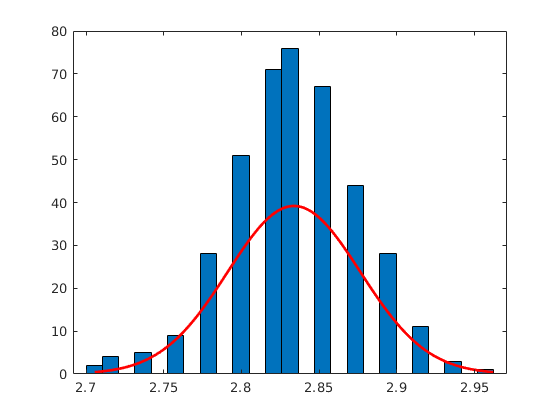

height = 66

width = 53

no_of_nan = 0

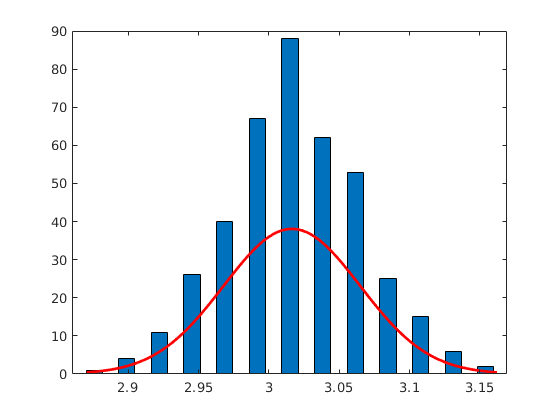

height = 68

width = 27

no_of_nan = 0

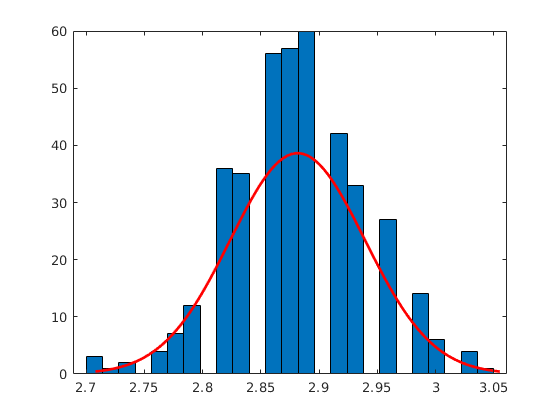

height = 53

width = 76

no_of_nan = 0

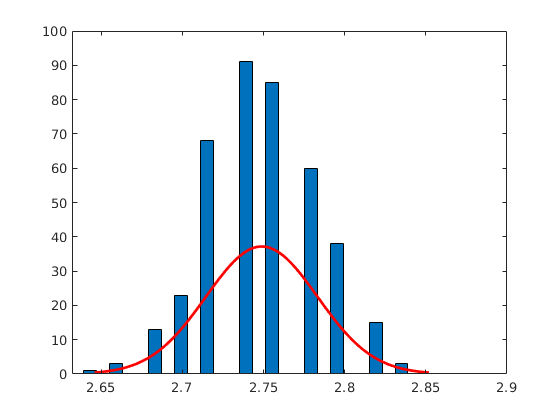

height = 65

width = 27

no_of_nan = 0

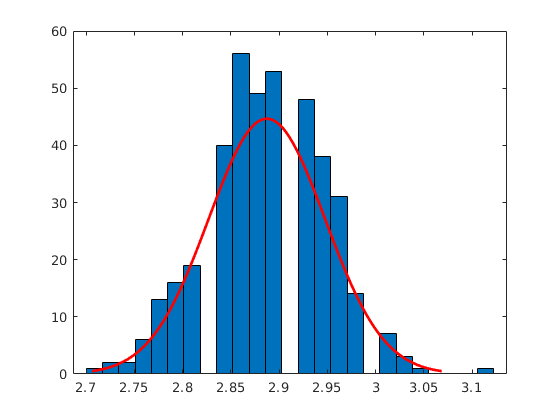

height = 32

width = 74

no_of_nan = 0

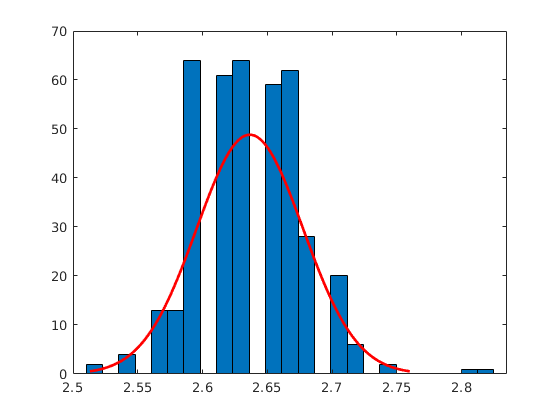

height = 76

width = 29

no_of_nan = 0

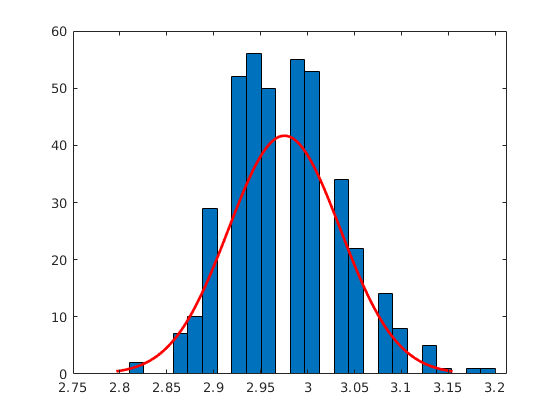

height = 56

width = 65

no_of_nan = 0

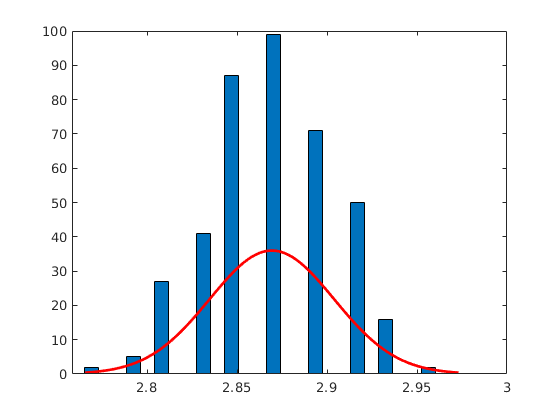

height = 66

width = 58

no_of_nan = 0

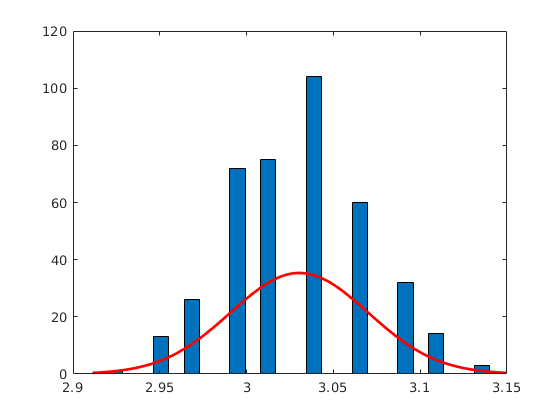

height = 69

width = 27

no_of_nan = 0

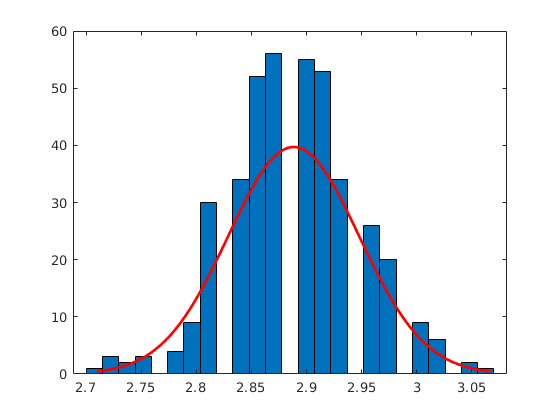

height = 65

width = 50

no_of_nan = 0

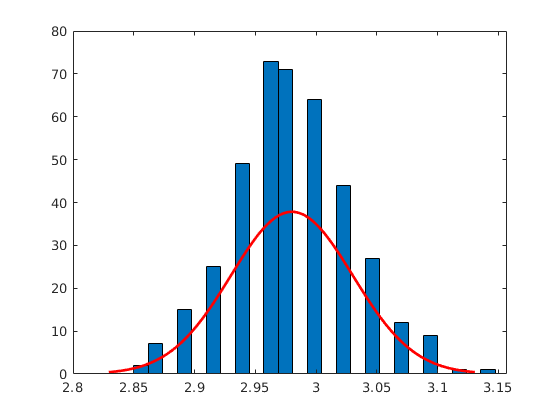

height = 36

width = 86

no_of_nan = 0

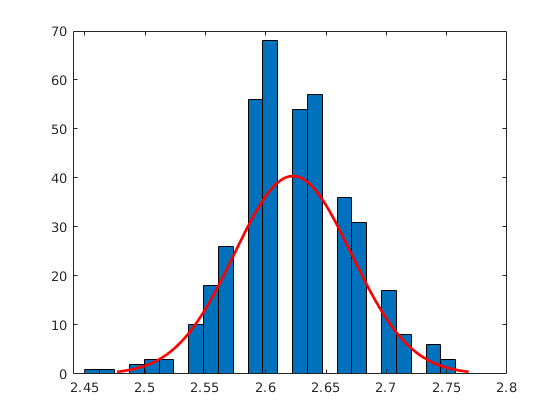

height = 62

width = 49

no_of_nan = 0

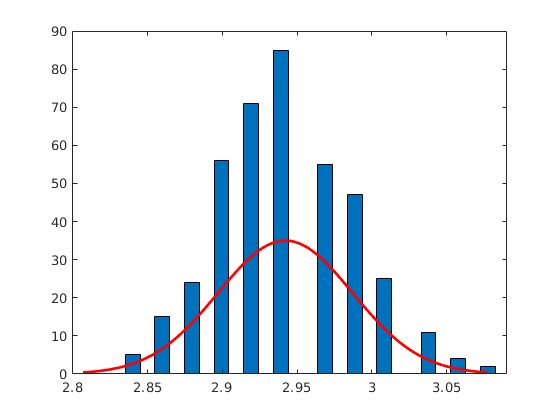

height = 46

width = 22

no_of_nan = 0

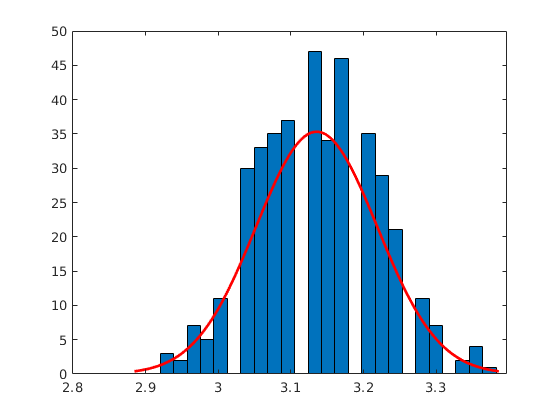

height = 64

width = 65

no_of_nan = 0

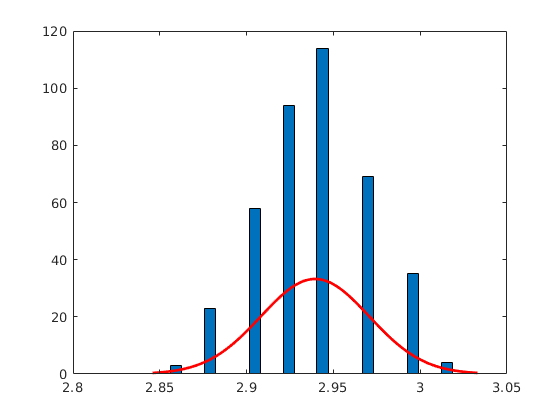

height = 21

width = 56

no_of_nan = 0

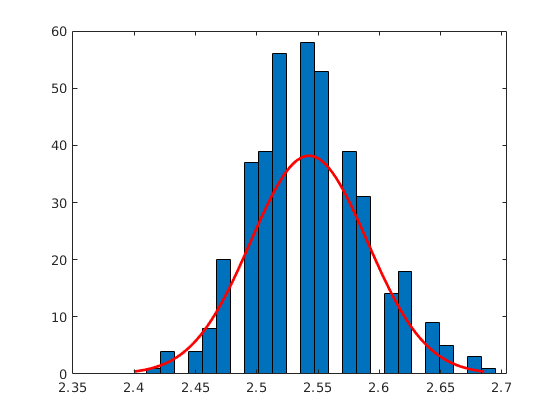

height = 41

width = 14

no_of_nan = 0

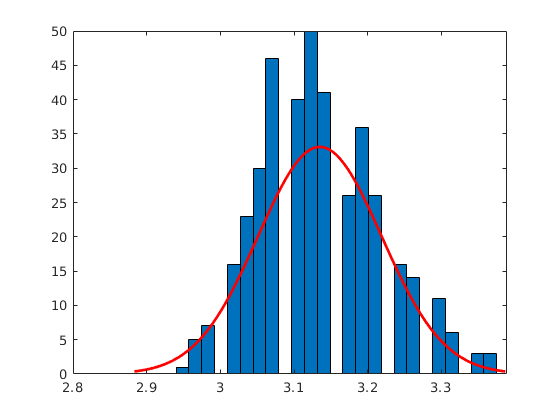

height = 59

width = 47

no_of_nan = 0

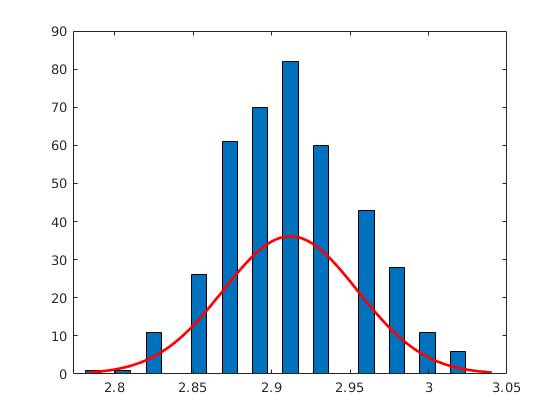

height = 28

width = 33

no_of_nan = 0

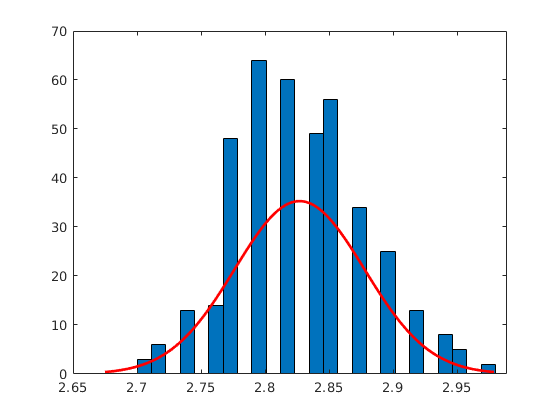

height = 77

width = 63

no_of_nan = 0

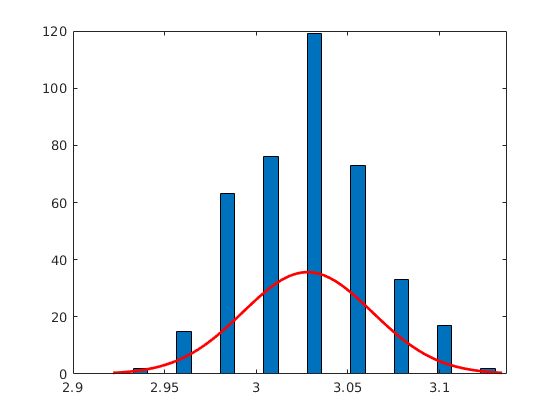

height = 78

width = 39

no_of_nan = 0

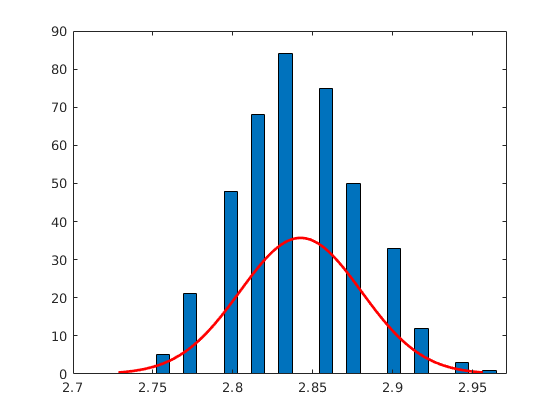

height = 68

width = 63

no_of_nan = 0

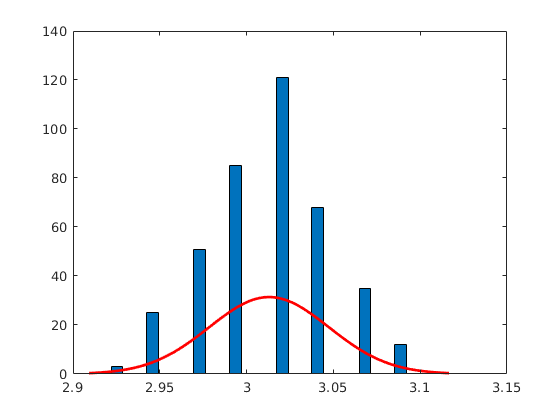

height = 76

width = 38

no_of_nan = 0

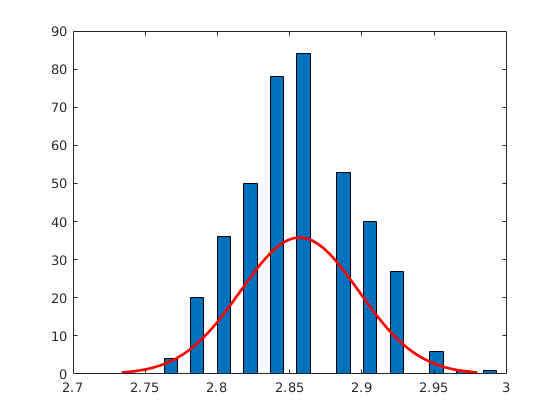

height = 61

width = 67

no_of_nan = 0

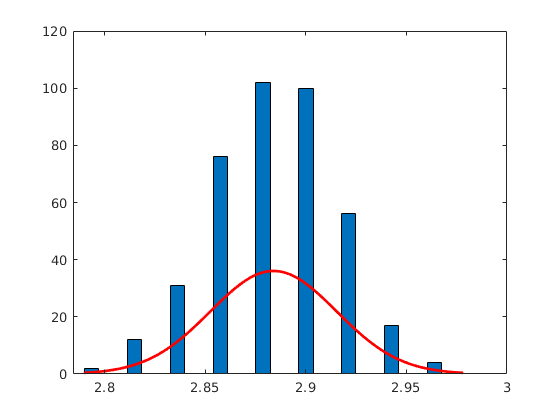

height = 19

width = 44

no_of_nan = 0

height = 51

width = 26

no_of_nan = 0

height = 22

width = 59

no_of_nan = 0

height = 72

width = 33

no_of_nan = 0

height = 64

width = 62

no_of_nan = 0

height = 65

width = 62

no_of_nan = 0

height = 40

width = 14

no_of_nan = 0

height = 29

width = 73

no_of_nan = 0

height = 42

width = 27

no_of_nan = 0

height = 43

width = 24

no_of_nan = 0

height = 50

width = 76

no_of_nan = 0

height = 39

width = 44

no_of_nan = 0

height = 75

width = 36

no_of_nan = 0

height = 78

width = 57

no_of_nan = 0

height = 32

width = 74

no_of_nan = 0

height = 35

width = 70

no_of_nan = 0

height = 74

width = 43

no_of_nan = 0

height = 72

width = 60

no_of_nan = 0

height = 61

width = 28

no_of_nan = 0

height = 81

width = 51

no_of_nan = 0

height = 67

width = 25

no_of_nan = 0

height = 71

width = 35

no_of_nan = 0

height = 17

width = 38

no_of_nan = 0

height = 20

width = 57

no_of_nan = 0

height = 74

width = 54

no_of_nan = 0

height = 76

width = 45

no_of_nan = 0

height = 32

width = 51

no_of_nan = 0

height = 78

width = 32

no_of_nan = 0

height = 74

width = 56

no_of_nan = 0

height = 33

width = 50

no_of_nan = 0

height = 61

width = 66

no_of_nan = 0

height = 73

width = 61

no_of_nan = 0

height = 73

width = 32

no_of_nan = 0

height = 69

width = 56

no_of_nan = 0

height = 78

width = 42

no_of_nan = 0

height = 74

width = 54

no_of_nan = 0

height = 79

width = 44

no_of_nan = 0

height = 42

width = 28

no_of_nan = 0

height = 62

width = 49

no_of_nan = 0

height = 40

width = 13

no_of_nan = 0

height = 75

width = 37

no_of_nan = 0

height = 52

width = 44

no_of_nan = 0

height = 32

width = 58

no_of_nan = 0

height = 51

width = 18

no_of_nan = 0

height = 42

width = 43

no_of_nan = 0

height = 46

width = 25

no_of_nan = 0

height = 62

width = 67

no_of_nan = 0

height = 48

width = 16

no_of_nan = 0

height = 77

width = 60

no_of_nan = 0

height = 51

width = 76

no_of_nan = 0

height = 38

width = 13

no_of_nan = 0

height = 37

width = 44

no_of_nan = 0

height = 65

width = 28

no_of_nan = 0

height = 21

width = 54

no_of_nan = 0

height = 40

width = 20

no_of_nan = 0

height = 50

width = 6

no_of_nan = 0

height = 52

width = 7

no_of_nan = 0

height = 68

width = 27

no_of_nan = 0

height = 74

width = 45

no_of_nan = 0

height = 72

width = 36

no_of_nan = 0

height = 29

width = 33

no_of_nan = 0

height = 18

width = 50

no_of_nan = 0

height = 42

width = 43

no_of_nan = 0

height = 72

width = 41

no_of_nan = 0

height = 80

width = 37

no_of_nan = 0

height = 18

width = 48

no_of_nan = 0

height = 44

width = 26

no_of_nan = 0

height = 18

width = 37

no_of_nan = 0

height = 81

width = 53

no_of_nan = 0

height = 37

width = 20

no_of_nan = 0

height = 19

width = 51

no_of_nan = 0

height = 55

width = 27

no_of_nan = 0

height = 32

width = 52

no_of_nan = 0

height = 81

width = 44

no_of_nan = 0

height = 19

width = 49

no_of_nan = 0

height = 39

width = 18

no_of_nan = 0

height = 81

width = 46

no_of_nan = 0

height = 37

width = 43

no_of_nan = 0

height = 76

width = 33

no_of_nan = 0

height = 74

width = 62

no_of_nan = 0

height = 22

width = 51

no_of_nan = 0

height = 76

width = 62

no_of_nan = 0

no_of_plots_for_distribution = 1000;

xy_index_matrix = rand(2,no_of_plots_for_distribution);
xy_index_matrix(1,:) = ceil(xy_index_matrix(1,:)*91);
xy_index_matrix(2,:) = ceil(xy_index_matrix(2,:)*111);

for i=1:no_of_plots_for_distribution
    if(abs(Z_score_matrix(xy_index_matrix(1,i),xy_index_matrix(2,i)))>10)
        vec_of_points = glare_tensor(xy_index_matrix(1,i),xy_index_matrix(2,i),:);
        vec_of_point = reshape(vec_of_points, [1,sample_count]);
        pointDistribution(vec_of_point,xy_index_matrix(1,i),xy_index_matrix(2,i),sample_count);       
    end    
end

function pointDistribution(point_vec,height,width,sample_count)
figure
height
width
no_of_nan = sum(isnan(point_vec))
if(no_of_nan<sample_count)
    histfit(point_vec,25,'normal')
else
    t = "all values Nan so distribution plot not possible"
end
end
function Z_score_matrix = classifyPoint(mean_map,stddev_map,no_of_nan_mat,wo_mean_map,wo_stddev_map,wo_no_of_nan_mat)

Z_score_matrix = zeros(size(mean_map));

difference_matrix = 1000*(wo_mean_map - mean_map);
sq_rt_no_of_nan_mat = no_of_nan_mat.^0.5;
intermediate_mat = (wo_mean_map - mean_map).*sq_rt_no_of_nan_mat;

Z_score_matrix = intermediate_mat./stddev_map;
max(Z_score_matrix)

end

function plotter(width,height,individual_callbacks,title_,z_label,save_,z_lim)
figure
if(z_lim == 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
if(z_lim ~= 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    zlim([0,z_lim]);
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
end